HOMEWORK PROBLEM 5

%Stuff For Calculating Stencil Coefficients

%Xbar Chosen For Trivial Values
xbar = 1;

%Assortment of different h values to try 
hvals = logspace(0,-2,13);

%Distances for different stenicls
array1 = [0, 1, 2, 3];
array2 = [-1, 0, 1, 2, 3];
array3 = [-3, -2, -1, 0, 1, 2, 3];

%Preallocated Coefficient Matricies
coefs1 = zeros(4,13);
coefs2 = zeros(5,13);
coefs3 = zeros(7,13);

%///////////////////////////////////////////////

%Stuff For Calculating Logplots

% Function & Actual Derivative
u = @(x) sin(2*x);
du = @(x) 2*cos(2*x);

% Vectors For Error
error1 = h*hvals;
error2 = h*hvals;
error3 = h*hvals;

% Approximate Derrivatives
approxDer1 = zeros(1,13);
approxDer2 = zeros(1,13);
approxDer3 = zeros(1,13);

% Actual Derivative
actual = du(xbar);

Stencil 1: 0,h,2h,3h


for i = 1: length(hvals)
    
    %Determine xvals based off array and hvals
    xvals = xbar + hvals(i) * array1;
    
    %Find Coefficients from Stencil
    coefs1(:,i) = findFDCoefs(3,xbar,xvals);
   
end

%Demonstrate Assortment of Coefficients From logspace values
disp("First Stencil Coefficients With Varying h: ");

First Stencil Coefficients With Varying h: 


disp(coefs1);

   1.0e+06 *

   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0003   -0.0010   -0.0032   -0.0100   -0.0316   -0.1000   -0.3162   -1.0000
    0.0000    0.0000    0.0000    0.0001    0.0003    0.0009    0.0030    0.0095    0.0300    0.0949    0.3000    0.9487    3.0000
   -0.0000   -0.0000   -0.0000   -0.0001   -0.0003   -0.0009   -0.0030   -0.0095   -0.0300   -0.0949   -0.3000   -0.9487   -3.0000
    0.0000    0.0000    0.0000    0.0000    0.0001    0.0003    0.0010    0.0032    0.0100    0.0316    0.1000    0.3162    1.0000



Stencil 2: -h, 0, h, 2h,3h


for i = 1: length(hvals)
    
    %Determine xvals based off array and hvals
    xvals = xbar + hvals(i) * array2;
    
    %Find Coefficients from Stencil
    coefs2(:,i) = findFDCoefs(3,xbar,xvals);
   
end

%Demonstrate Assortment of Coefficients From logspace values
disp("Second Stencil Coefficients With Varying h: ");

Second Stencil Coefficients With Varying h: 


disp(coefs2);

   1.0e+06 *

   -0.0000   -0.0000   -0.0000   -0.0000   -0.0002   -0.0005   -0.0015   -0.0047   -0.0150   -0.0474   -0.1500   -0.4743   -1.5000
    0.0000    0.0000    0.0000    0.0002    0.0005    0.0016    0.0050    0.0158    0.0500    0.1581    0.5000    1.5811    5.0000
   -0.0000   -0.0000   -0.0001   -0.0002   -0.0006   -0.0019   -0.0060   -0.0190   -0.0600   -0.1897   -0.6000   -1.8974   -6.0000
    0.0000    0.0000    0.0000    0.0001    0.0003    0.0009    0.0030    0.0095    0.0300    0.0949    0.3000    0.9487    3.0000
   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0002   -0.0005   -0.0016   -0.0050   -0.0158   -0.0500   -0.1581   -0.5000



Stencil 3: -3h, -2h, -h, 0, h, 2h,3h

for i = 1: length(hvals)
    
    %Determine xvals based off array and hvals
    xvals = xbar + hvals(i) * array3;
    
    %Find Coefficients from Stencil
    coefs3(:,i) = findFDCoefs(3,xbar,xvals);
   
end

%Demonstrate Assortment of Coefficients From logspace values
disp("Third Stencil Coefficients With Varying h: ");

Third Stencil Coefficients With Varying h: 


disp(coefs3);

   1.0e+06 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0004    0.0012    0.0040    0.0125    0.0395    0.1250
   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0003   -0.0010   -0.0032   -0.0100   -0.0316   -0.1000   -0.3162   -1.0000
    0.0000    0.0000    0.0000    0.0001    0.0002    0.0005    0.0016    0.0051    0.0162    0.0514    0.1625    0.5139    1.6250
         0    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
   -0.0000   -0.0000   -0.0000   -0.0001   -0.0002   -0.0005   -0.0016   -0.0051   -0.0162   -0.0514   -0.1625   -0.5139   -1.6250
    0.0000    0.0000    0.0000    0.0000    0.0001    0.0003    0.0010    0.0032    0.0100    0.0316    0.1000    0.3162    1.0000
   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0004   -0.0012   -0.0040   -0.0125   -0.0395   -0.1250



Stencil 1 Logplot

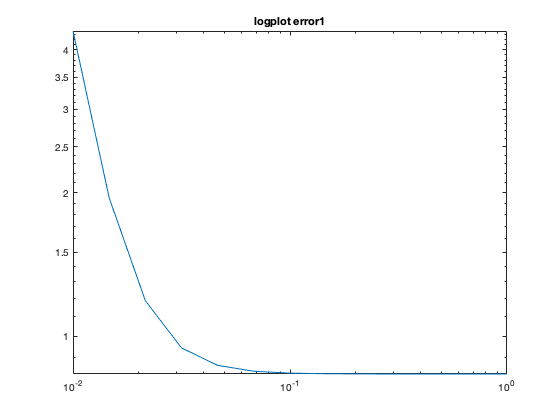

% Calculate xvals for Stencil 1
for i = 1: length(hvals)
    
    xvals1 = xbar + hvals(i) * array1;
end

% Make function Values
fvals1 = u(xvals1);

%Calculate Derivative & Error
for i = 1: length(hvals)
    
    approxDer1(1,i) = dot(coefs1(:,i),fvals1);
    
    error1(1,i) = abs(approxDer1(1,i)-actual);
end

%Plot Error
figure(1);
loglog(hvals,error1);
title("logplot error1");

Stencil 2 Logplot

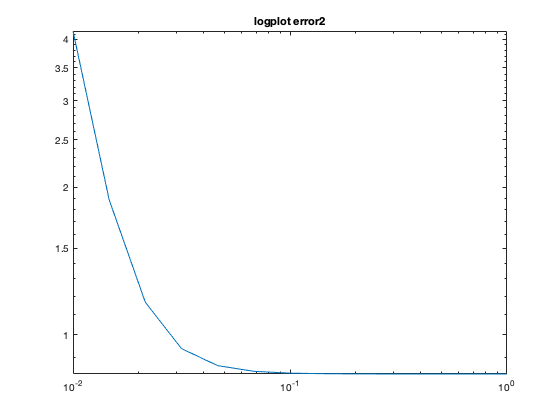

% Calculate xvals for Stencil 2
for i = 1: length(hvals)
    
    xvals2 = xbar + hvals(i) * array2;
end

% Make function Values
fvals2 = u(xvals2);

% Calculate Derivative & Error
for i = 1: length(hvals)
    
    approxDer2(1,i) = dot(coefs2(:,i),fvals2);
    
    error2(1,i) = abs(approxDer2(1,i)-actual);
end

% Plot Error
figure(2);
loglog(hvals,error2);
title("logplot error2");

Stencil 3 Logplot

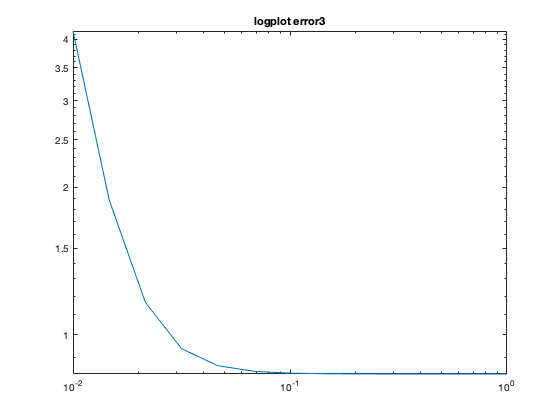

% Calculate xvals for Stencil 3
for i = 1: length(hvals)
    
    xvals3 = xbar + hvals(i) * array3;
end

% Make function Values
fvals3 = u(xvals3);

% Calculate Derivative & Error
for i = 1: length(hvals)
    
    approxDer3(1,i) = dot(coefs3(:,i),fvals3);
    
    error3(1,i) = abs(approxDer3(1,i)-actual);
end

% Plot Error
figure(3);
loglog(hvals,error3);
title("logplot error3");

Conclusion: The error order is non-linear on log-log plot, so the order of error must be exponential rather than O(h^q) as is typical. 